# Введение в MATLAB

## 1 Переменные

Куда сохраняется вычисленное значение?

2

ans = 2

Если написать число или выражение без оператора присваивания (`=`), то результат сохранится в переменную `ans`

5 * 7

ans = 35

Чтобы сохранить результат в переменную, нужно назвать переменную корректным именем (начать с латинской буквы, использовать только их, символы подчеркивания и цифры), написать знак присвоения, после чего записать выражение

variable = 6

variable = 6

namelengthmax %максимальная длина имени переменной, проверьте, что будет, если задать имя длиннее :)

ans = 63

Имя чувствительно к регистру

a = 4

a = 4

A = 3 % переменные a и A не совпадают

A = 3

Чтобы скрыть результат операции, достаточно поставить в конце выражения `;`

ans;

## 2 Типы данных

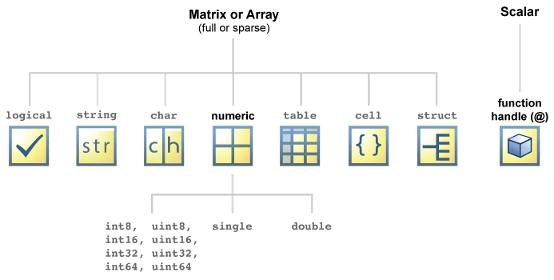

class(true) % логический тип

ans = 'logical'

class(2.3) % число двойной точности

ans = 'double'

class(uint8(-1)) % целое беззнаковое число, размера 8 бит

ans = 'uint8'

class("This is a string") % строка

ans = 'string'

class('a') % символ, обязательно в одинарных ковычках

ans = 'char'

c = {"abc", 1; 2, "ggg"} % ячейка

c = 2×2 cell array
    {["abc"]}    {[    1]}
    {[    2]}    {["ggg"]}


c{1,2} %обращение к элементу ячейки

ans = 1

class(c)

ans = 'cell'

Формат вывода чисел

format long
1 / 3 % 15 знаков после запятой

ans =    0.333333333333333


format short
1 / 3 % 4 знака после запятой

ans = 0.3333

## 3 Математические операции

Арифметические операции

a = 2

a = 2

b = 3

b = 3


a + b % сложение

ans = 5

a - b % вычитание

ans = -1

a / b % деление

ans = 0.6667

a * b % умножение

ans = 6

a ^ b % возведение в степень

ans = 8

Операторы сравнения

a == b % сравнение на равенство

ans = logical
   0


a > b % больше

ans = logical
   0


a <= b % меньше или равно

ans = logical
   1


a ~= b % не равно

ans = logical
   1


Логические операторы

true & false % логическое "И"

ans = logical
   0


true | false % логическое "ИЛИ"

ans = logical
   1


Математические и физические константы

pi % число пи

ans = 3.1416

1i % мнимая единица

ans = 0.0000 + 1.0000i

physconst("Lightspeed") % скорость света

ans = 299792458

Математические функции

sin(pi) % синус

ans = 1.2246e-16

abs(-2) % модуль

ans = 2

log2(8) % двоичный логарифм

ans = 3

sqrt(-9) % квадратный корень

ans = 0.0000 + 3.0000i

## 4 Матрицы

x = [3 5] % вектор-строка

x =      3     5


y = [1; 3] % вектор-столбец

y =      1
     3


z = [3 4 5; 6 7 8] % матрица 2х3

z =      3     4     5
     6     7     8


c = [abs(-2), 4^2, pi*3]

c =     2.0000   16.0000    9.4248


Размер матрицы

size(c)

ans =      1     3


Создание векторов-строк

sc1 = 5 : 8 % заполнение строки числами с 5 до 8 с шагом 1

sc1 =      5     6     7     8


sc2 = 20 : 2 : 26 % заполнение строки числами с 20 до 26 с шагом 2

sc2 =     20    22    24    26


linspace(1, 4, 5) % создание строки длины 5, заполненной числами от 1 до 4

ans =     1.0000    1.7500    2.5000    3.2500    4.0000


Транспонирование

a = 1 : 3

a =      1     2     3


a = a' % получаем вектор-столбец

a =      1
     2
     3


x = (1 : 5)' % получаем вектор-столбец в одну строку

x =      1
     2
     3
     4
     5


Заполнение матриц

rand(2, 3) % случайными числами

ans =     0.8143    0.9293    0.1966
    0.2435    0.3500    0.2511


ones(5) % единицами

ans =      1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1


zeros(1, 2) % нулями

ans =      0     0


### Индексация

A = [-3 pi^2 4.567]

A =    -3.0000    9.8696    4.5670


B = [1 2 3; 4 5 6; 7 8 9]

B =      1     2     3
     4     5     6
     7     8     9


C = rand(5, 3)

C =     0.6160    0.5497    0.3804
    0.4733    0.9172    0.5678
    0.3517    0.2858    0.0759
    0.8308    0.7572    0.0540
    0.5853    0.7537    0.5308


Второй элемент вектора A

A(2) = 10

A =    -3.0000   10.0000    4.5670


Доступ к элементу матрицы B с индексами `(3, 2)`

B(end, end - 1)

ans = 8

Получение подматриц

x = C(2, :) % вектор из второй строки

x =     0.4733    0.9172    0.5678


C(1 : 3, :) % первые три строки, все стобцы

ans =     0.6160    0.5497    0.3804
    0.4733    0.9172    0.5678
    0.3517    0.2858    0.0759


C([1, 3], :) % первая и третья строки, все столбцы

ans =     0.6160    0.5497    0.3804
    0.3517    0.2858    0.0759


### Операции над матрицами и векторами

row = rand(1, 5)

row =     0.7792    0.9340    0.1299    0.5688    0.4694


column = rand(5, 1)

column =     0.0119
    0.3371
    0.1622
    0.7943
    0.3112


scalar = row * column

scalar = 0.9431

matrix = column * row

matrix =     0.0093    0.0111    0.0015    0.0068    0.0056
    0.2627    0.3149    0.0438    0.1918    0.1582
    0.1264    0.1515    0.0211    0.0923    0.0761
    0.6189    0.7419    0.1032    0.4518    0.3728
    0.2425    0.2907    0.0404    0.1770    0.1461


### Полезные функции для работы с матрицами

a = [1 6 3 4]

a =      1     6     3     4


[v, i] = max(a) % значение и индекс максимального элемента вектора a

v = 6

i = 2

m = max(a) % значение максимального элемента вектора a

m = 6

Максиумы, минимумы, суммы

D = [4 3 5; 6 7 2; 3 1 8]

D =      4     3     5
     6     7     2
     3     1     8


[V, I] = min(D) % определение минимальных значений и их индексов в столбцах

V =      3     1     2


I =      3     3     2


M = max(D) % определение максимальных значений в столбцах

M =      6     7     8


sum(D) % суммирование значений в столбцах

ans =     13    11    15


min_in_row = min(D, [], 2) % определение минимальных значений и их индексов в строках

min_in_row =      3
     2
     1


## 5 Условные операторы

`if <условие>`

`    <операторы>`

`elseif <условие>`

`    <операторы>`

`else`

`    <операторы>`

`end`

a = 10

a = 10

if a > 11
    fprintf("Число больше 11")
elseif a < 0
    fprintf("Число отрицательное")
else
    fprintf("Положительное число, меньше или равно 11")
end

Положительное число, меньше или равно 11

### Циклы for и while

`while <условие>`

`    <операторы>`

`end`

while a > 0
    a = a - 1
end

a = 9

a = 8

a = 7

a = 6

a = 5

a = 4

a = 3

a = 2

a = 1

a = 0

`for <счетчик> = <начальное значение>:<шаг>:<конечное значение>`

`    <операторы>`

`end`

for i = 1 : 2 : 5
    a = a + 1
end

a = 1

a = 2

a = 3

Итерирование по вектору

for i = rand(1, 5)
    i
end

i = 0.5285

i = 0.1656

i = 0.6020

i = 0.2630

i = 0.6541